 Lianne Perez

Neesha Bonadie

**Lab 1: Time-Domain Analysis of Discrete-TIme Systems Part I**

**Abstract**

In this lab the concept of discrete time-signals was explored. In Part A, different discrete time signals were plotted and the changes in graphs after applying different transformations on different discrete plots was investigated. With that acquired knowledge sampling of discrete signals was then looked into. For Part B a system equation for a bank account with money being deposited and interest being added was derived. Then two plots were made showing what the account looked like in 12 months when no money is deposited compared to when $100 is deposited every month. In Part C, a filter is designed to find the maximum point of an input signal then displays the maximum point at the output. For Part D, two functions were made to calculate the energy and the power of a vector. Using the functions, the energy and power of the function x[n] was found.

**A. Signal Transformation**

**1)**

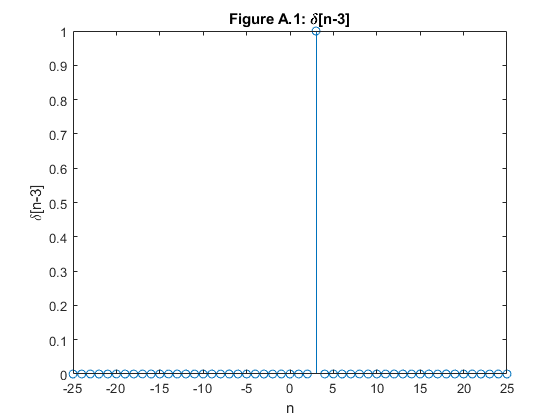

% shifting and time reversal transformations on a discrete time signal

% domain
n = -25 : 1 : 25;

% i) delta[n-3]
delta = @(n) (1.*(n > 2) & (n < 4));

figure(1);
stem(n, delta(n));
title('Figure A.1: \delta[n-3]');
xlabel('n'); ylabel('\delta[n-3]');

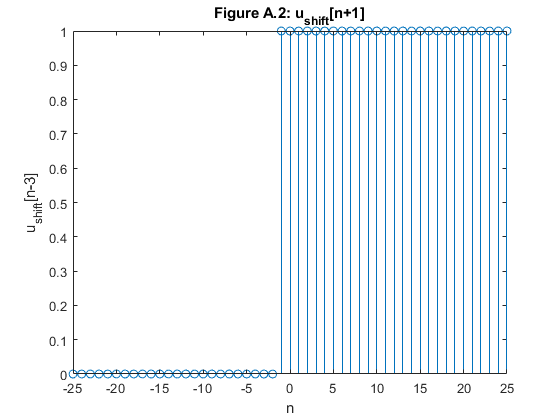

% ii) u[n+1]

% u[n] before shift
u = @(n) (1.*((n >= 0) & (n <= 25)));
% u[n+1]
u_shift = @(n) (1.*((n >= -1) & (n <= 25)));

figure(2);
stem(n, u_shift(n));
title('Figure A.2: u_{shift}[n+1]');
xlabel('n'); ylabel('u_{shift}[n-3]');

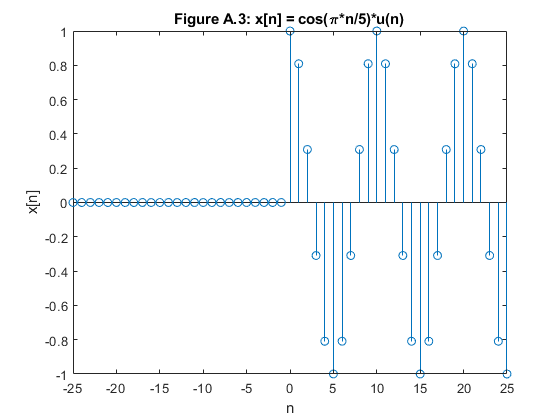

% iii) x[n] = cos(pi*n/5)*u[n]

x = @(n) cos((pi.*n) / 5).*u(n);

figure(3);
stem(n, x(n));
title('Figure A.3: x[n] = cos(\pi*n/5)*u(n)');
xlabel('n'); ylabel('x[n]');

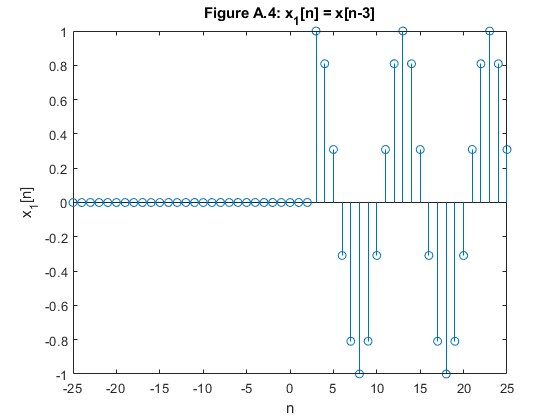

% iv) x1[n] = x[n-3]

x_2 = @(n) x(n-3);

figure(4);
stem(n, x_2(n));
title('Figure A.4: x_{1}[n] = x[n-3]');
xlabel('n'); ylabel('x_{1}[n]');

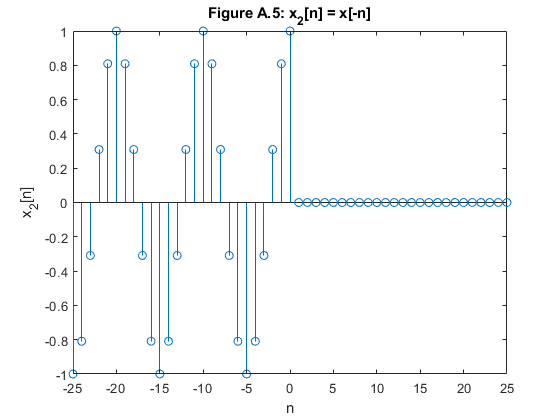

% v) x2[n] = x[-n]

x_2 = @(n) x(n);

figure(5);
stem(n, x(-n));
title('Figure A.5: x_{2}[n] = x[-n]');
xlabel('n'); ylabel('x_{2}[n]');

The function x1[n] is a transformation of x[n] shifted to the right by three; whereas x2[n] is a time reversal of x[n].

**2)**

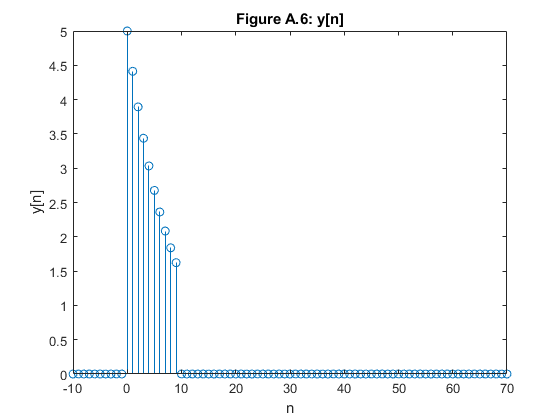

% effects of scaling on a discrete time signal

% domain
n = -10: 1: 70;

% i) y[n] = 5e^(-n/8)*(u[n]-u[n-10])

u = @(n) (1.*((n >= 0) & (n <= 70)));
y = @(n) (5.*(exp((-n) / 8)).*(u(n) - u(n-10)));

figure(6);
stem(n, y(n));
title('Figure A.6: y[n]');
xlabel('n'); ylabel('y[n]');

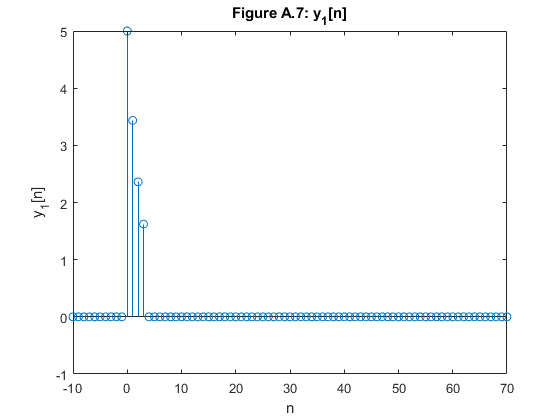


% ii) y1[n] = y[3n]

y_2 = @(n) y(3.*n);

figure(7);
stem(n, y_2(n));
title('Figure A.7: y_{1}[n]');
xlabel('n'); ylabel('y_{1}[n]');

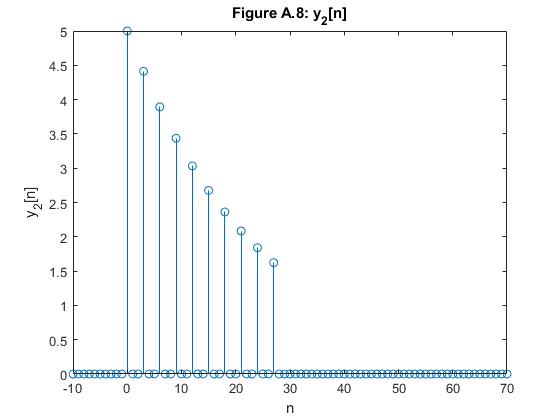


% iii) y2[n] = y[n/3]

y_2 = @(n) y(n/3).*(mod(n,3) == 0); %adds 2 zeros in between existing values, upsampling

figure(8);
stem(n, y_2(n));
title('Figure A.8: y_{2}[n]');
xlabel('n'); ylabel('y_{2}[n]');

The effects on scaling for y1[n] and y2[n] is that y1[n] is y[n] compressed by a factor of 3 and is downsampled; while y2[n] is expanded by a factor of 3 and is upsampled.

**3)**

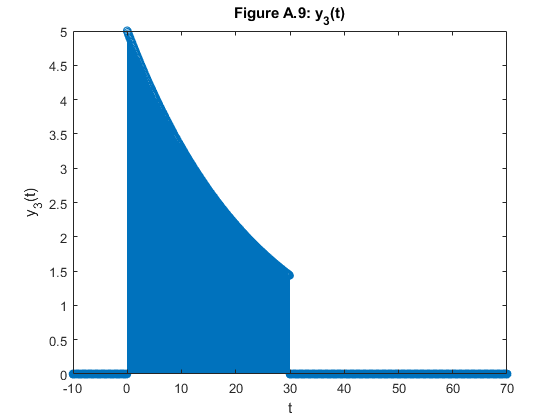

% CT signal: z(t) = 5*e^(-t/8)*(u(t)-u(t-10))
% where t = -10 : 0.1 : 70

t = -10 : 0.1 : 70;

u = @(t) (1.*((t >= 0) & (t <= 70)));
z = @(t) (5.*(exp((-t) / 8)).*(u(t) - u(t-10)));
% stem(t, z(t));

% i) y3(t) = z(t/3)

y_3 = @(t) z(t/3);

figure(9);
stem(t, y_3(t));
title('Figure A.9: y_{3}(t)');
xlabel('t'); ylabel('y_{3}(t)');

ii) The functions y2[n] and y3(t) are not the same because in discrete-time signals, when they are being compressed, zeros are added in between existing points from the original function. In y2[n], 2 zeros in between each points from y[n] were added; however, in y3(t), since it is a continous time signal, the function includes all the signals possible with the time expansion. 